# Non Parametric Statistics Using Resampling

*Bart Krekelberg - Last Update Jan 2023.*

## Standard non parametric tests

Matlab has several built-in functions that serve as non-parametric alternatives for some well-known tests. You can use these if your measurements do not have normally distributed noise. Note, however, that this comes at a cost; nonparametric tests are more likely to miss a true effect. This is commonly known as having low power, or an increased likelihood of type-II errors. (A Type-I error is mistakingly stating that an effect is signficant when it is not).

- Instead of the one-sample or paired `ttest` use `signrank`

- Instead of the two-sample `ttest2` use `ranksum`

- Instead of a one-way `anova1` use `kruskalwallis`

- Instead of a two-way `anova2` use `friedman`

That said, the Linear Mixed Models discussed in the Parametric Statistical Analysis Module are quite robust against violations of normality (as well as some other assumptions that parametric models often make). The BayesFactor toolbox ([available on GitHub](https://github.com/klabhub/bayesFactor/)) includes some tools (specifically, `lm.boostrap`, based on the boostrapping methods discussed below) that should help to determine whether you can use an LMM or need to use on of the nonparametric methods. 

## Bootstrap

Bootstrap resampling, or bootstrapping for short, is a technique used to generate robust estimates of confidence intervals for any value that you compute from your data. Its main appeal is that it (almost) always works and that it requires no assumptions of normality. The main downside is that it is computationally somewhat expensive, but for modern computers this is rarely an issue. 

To understand how or why bootstrapping works, it helps to think of an experiment as a statistician. Conisder an experiment in which we count the spikes that a neuron generates. In the statistician's view, there is a true distribution of spike counts (also called the population of spike counts; this is unknown to the experimenter). In each trial, the experimenter observes one value from this distribution, and the complete set of observations is called the sample. The goal of any experiment is to use the sample to estimate properties of the (underlying true) distribution.

To illustrate this, we'll pretend to be the all-knowing observer who knows that the neuron's true spike rate is 30 spikes/second and the spike counts have a Poisson distribution. With these assumptions we can approximate the population distribution by simulating a lot of trials, and visualize this true underlying distribution by showing a dot for each possible spike count: 

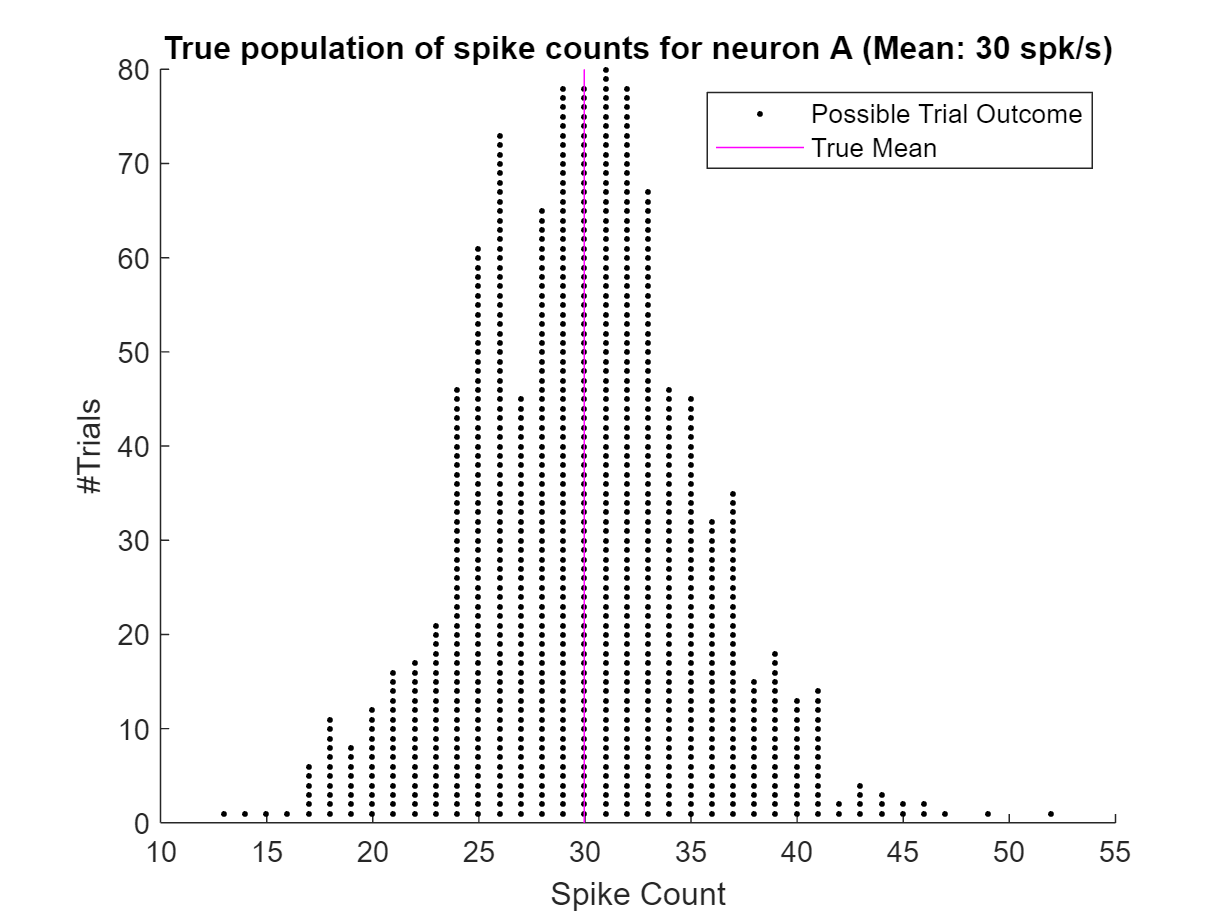

rateBefore  = 30; % Neuron A fires at 30 spikes/s
nrTrialsToSimulatePopulation = 1000;
% Draw spike counts from a Poisson distribution with mean 30 spk/s
rng default;
spikeCountBefore = poissrnd(rateBefore,[1 nrTrialsToSimulatePopulation]);
trueMean = mean(spikeCountBefore);
% Use a function (below) to bin spike counts and show a histogram
clf;
[~,~,h] = countSpikes(spikeCountBefore,'k.');
title(sprintf('True population of spike counts for neuron A (Mean:%3.3g spk/s)',trueMean))
hL = line([trueMean trueMean],ylim,'Color','m');
legend ([h,hL],'Possible Trial Outcome','True Mean')

Each dot here represents a possible experimentlal trial , all dots together represent the universe of all possible observations from this neuron. Now let's turn to the experimenter, who is unaware of this underlying distribution but performs measurements to assess its properties.

### A simulated experiment

In the statistician's view, an experiment is a random draw from this (unknowable) bucket of all possible observations. 

In this case, we know the unknowable so we can simulate an experiment in which we record a set number of trials by sampling `nrTrials` spike count observations from the underlying population. 

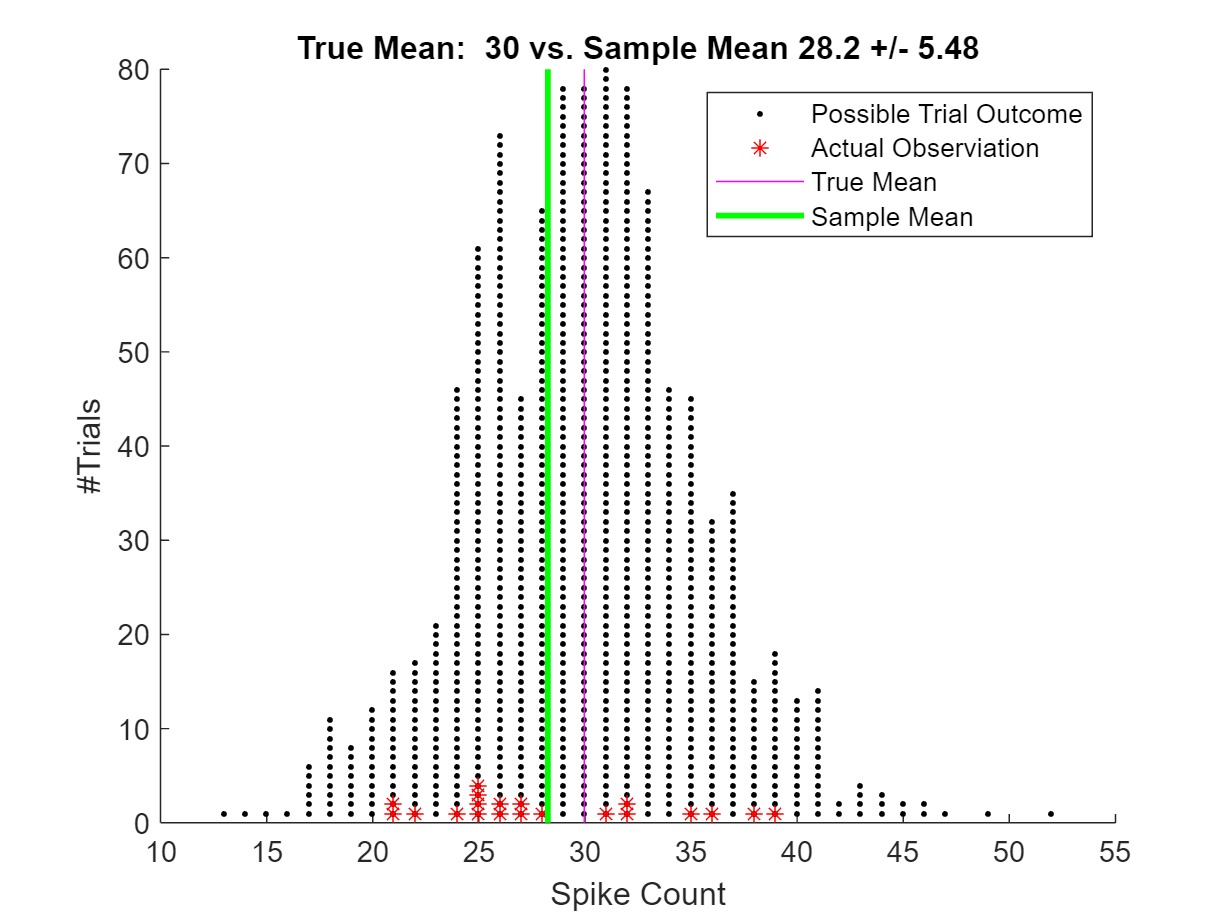

nrTrialsAfter = 20;
% Pick nrTrials unique trials from the underlying distribution (i.e. sample
% without replacement)
rng default
pickTrials= randperm(nrTrialsToSimulatePopulation,nrTrialsAfter);
exptSpikeCountA = spikeCountBefore(pickTrials);
% Count spikes in these trials
% And show them on top of the underlying distribution
figure
[~,~,h] = countSpikes(spikeCountBefore,'k.');
[exptNrTrials,exptNrSpikes,hS] = countSpikes(exptSpikeCountA,'r*');
hL = line([trueMean trueMean],ylim,'Color','m');
sampleMean = mean(exptSpikeCountA);
sampleStd = std(exptSpikeCountA);
hM = line([sampleMean sampleMean],ylim,'Color','g','LineWidth',2);
title(sprintf('True Mean: %3.3g vs. Sample Mean %3.3g +/- %3.3g',trueMean,sampleMean,sampleStd))
legend([h hS hL hM],'Possible Trial Outcome','Actual Observiation','True Mean','Sample Mean');

The red asterisks represent the experimenter's observations (the sample). In the real world, this would be all we've got to estimate properties of the underlying distribution.  For instance, we may be interested in the mean spike count of the neuron:This shows that the sample mean is indeed a reasonable estimate of the true mean.

Typically , an experimenter will also want to estimate confidence limits on this estimate. If one is willing to make the assumption that the measurements are drawn from a  normal distribution, then the standard error in the mean could be used to estimate the confidence limts. For instance, for a 95% confidence interval: 

sampleSte  = std(exptSpikeCountA)/sqrt(nrTrialsAfter);
% We can use the inverse of the normal cumulative distribution to calculate
% the spike count that is larger than 97.5% of all values:
normalUpper = norminv(0.975,sampleMean,sampleSte);
% and the same for the value that is smaller than the 2.5% of all values.
normalLower = norminv(0.025,sampleMean,sampleSte);
% Together these span the 95% confidence interval.
fprintf('Sample mean %3.3g (95%% CI: [%3.3g, %3.3g])',sampleMean,normalLower,normalUpper);

Sample mean 28.2 (95% CI: [25.9, 30.6])

Of course the problem is that the underlying distribution is *not* normal, so this calculation is **incorrect**. In general, there are many cases were we cannot or prefer not to make any assumptions about the underlying distributions. 

### Resampling 

To estimate confidence intervals you could repeat the experiment many times (each time collecting 20 trials), then make a histogram of the observed mean spike counts, and derive a range of likely values from this histogram. Performing more experiments, however, is expensive and time-consuming. The theoretical framework behind bootstrapping shows, however, that the next best thing is to draw trials from the sample that we already recorded (i.e, **resampling**). The underlying idea is that the sample (i.e. the distribution of red dots in the histogram above) is our best estimate of the underlying distribution (black dots). In other words, if a certain spike count occurs frequently in the red  histogram, then that probably means that it occurs frequently in the black histogram. Given that our sample provides our best estimate of the underlying distribution, we can essentially perform virtual experiments (with the same number of trials as the real experiment)  with outcomes (spike counts) that are drawn from the sample. Each such virtual experiment is called a bootstrap set:

nrBootstrapSets = 200;
% Preallocate space to store the values for each bootstrap set.
meanRate = nan(nrBootstrapSets,1);
for i=1:nrBootstrapSets
    % From the trials we recorded, we sample nrTrials, with replacement.
    % This is a simulation of another outcome of our experiment (with the same number of trials) that is just as likely as the one we actually got.
    trialsInThisSet = randi(nrTrialsAfter,[nrTrialsAfter 1]); % Sample with replacement
    meanRate(i) = mean(exptSpikeCountA(trialsInThisSet));     % Determine the mean over this set
end

Note that we draw from the sample ***with replacement*** ; that ensures that outcomes (spike counts) that occur more frequently in the sample, also occur more frequently in the bootstrap sets (at least on average). That is key to bootstrapping; by drawing observations from the actual sample, we approximate the true underlying distribution as best we can.

After the loop over bootstrap sets, the `meanRate `vector contains the mean spike count for each of the virtual experiments. We can compare the mean over the bootstrap sets to the sample mean. In general, these will be close and with a large enough number of bootstrap sets, the `bootstrapMean` will equal the `sampleMean`.

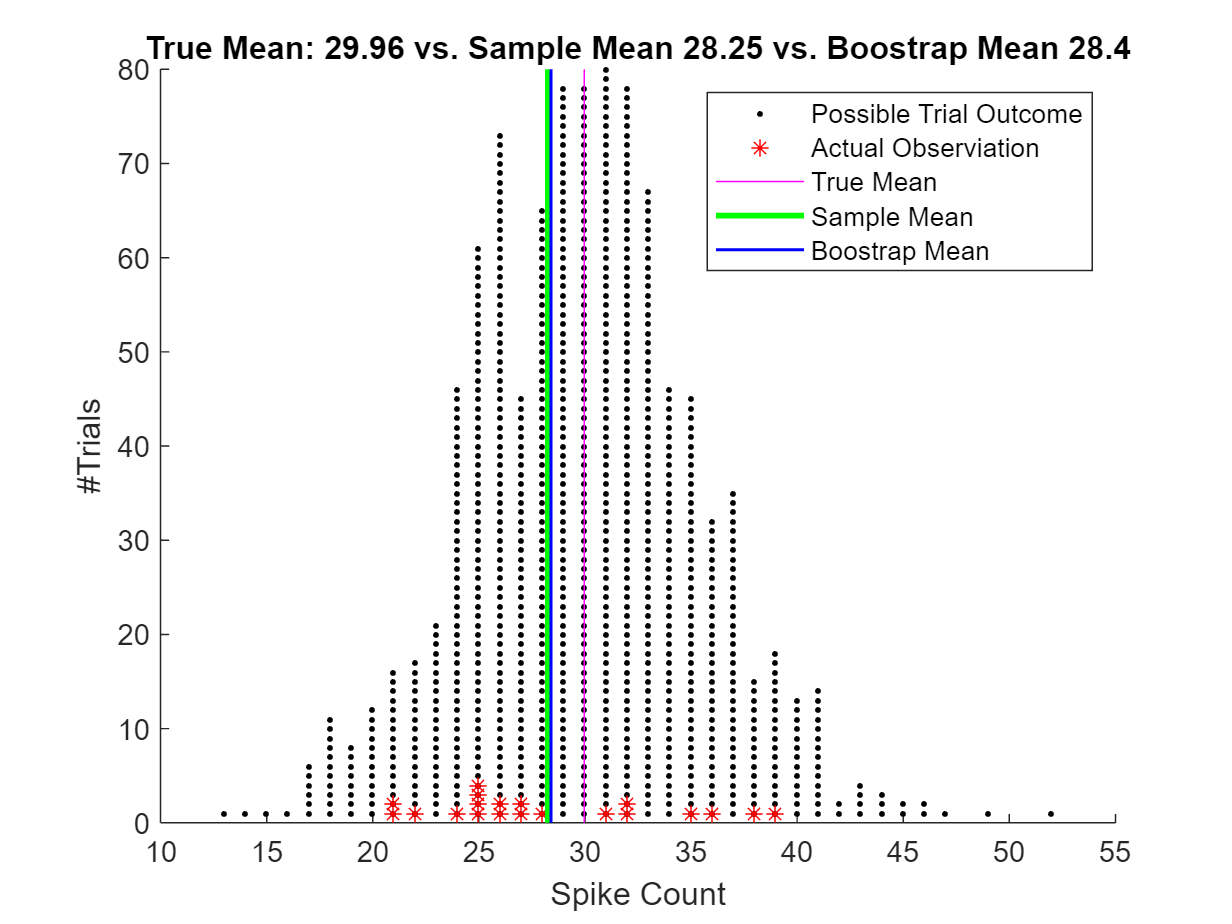

bootstrapMean = mean(meanRate);
hB = line([bootstrapMean bootstrapMean],ylim,'Color','b','LineWidth',1);
title(sprintf('True Mean: %3.4g vs. Sample Mean %3.4g vs. Boostrap Mean %3.4g',trueMean,sampleMean,bootstrapMean))
legend([h hS hL hM hB],'Possible Trial Outcome','Actual Observiation','True Mean','Sample Mean','Boostrap Mean');

The loop over bootstrap sets above shows explicitly how a sample is resampled in the bootstrap procedure. In production code, you should not do this, but use Matlab's `bootstrp` function, defined in the Statistics and Machine Learning Toolbox. With this function you specify the number of bootstrap sets , your analysis function, and the data, and Matlab returns the vector of results corresponding to each bootstrap set. The code above can be replaced with this two-liner:

% Bootstrap easy:  using bootstrp
% Bootstrap the analysis @mean on the sample exptSpikeCountA nrBoostrapSets
% times
nrBootstrapSets = 1000;
meanRate= bootstrp(nrBootstrapSets,@mean,exptSpikeCountA);
bootstrapMean = mean(meanRate);

### Confidence intervals

The main purpose of performing a bootstrap is to estimate confidence intevals.  To understand where these come from, lets look at the distribution of bootstrap means:

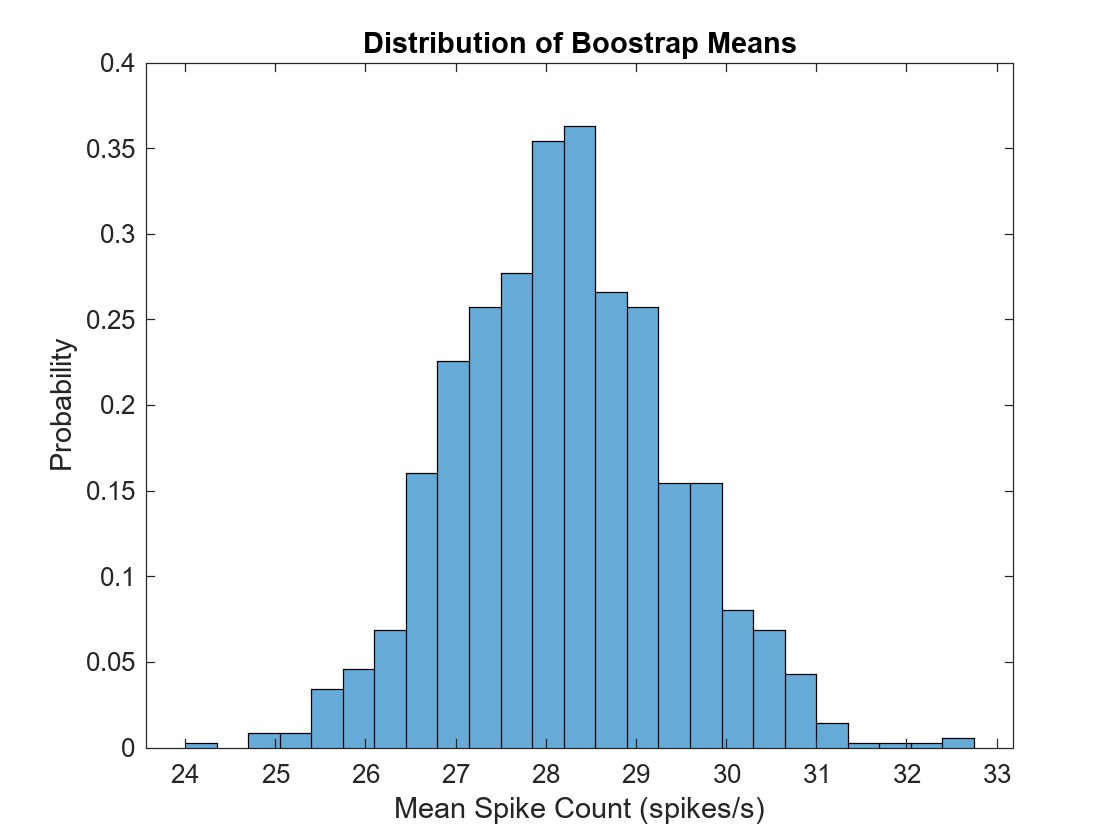

clf
histogram(meanRate,25,'Normalization','pdf')
xlabel 'Mean Spike Count (spikes/s)'
ylabel 'Probability'
title 'Distribution of Boostrap Means'

On the horizontal axis of this histogram is the quantity we are trying to estimate (in this case the *mean *spike count of neuron A), on the vertical axis we have the probability of obseriving this mean spike count in one of the bootstrap sets (i.e. the number of virtual experiments). This histogram tells us that , based on our sample, spike counts in the range 27-29 spikes/s are fairly common. while values above 30 or below 25 are rare. The simplest way to convert this into a confidence limit is to look at the cumulative distribution:

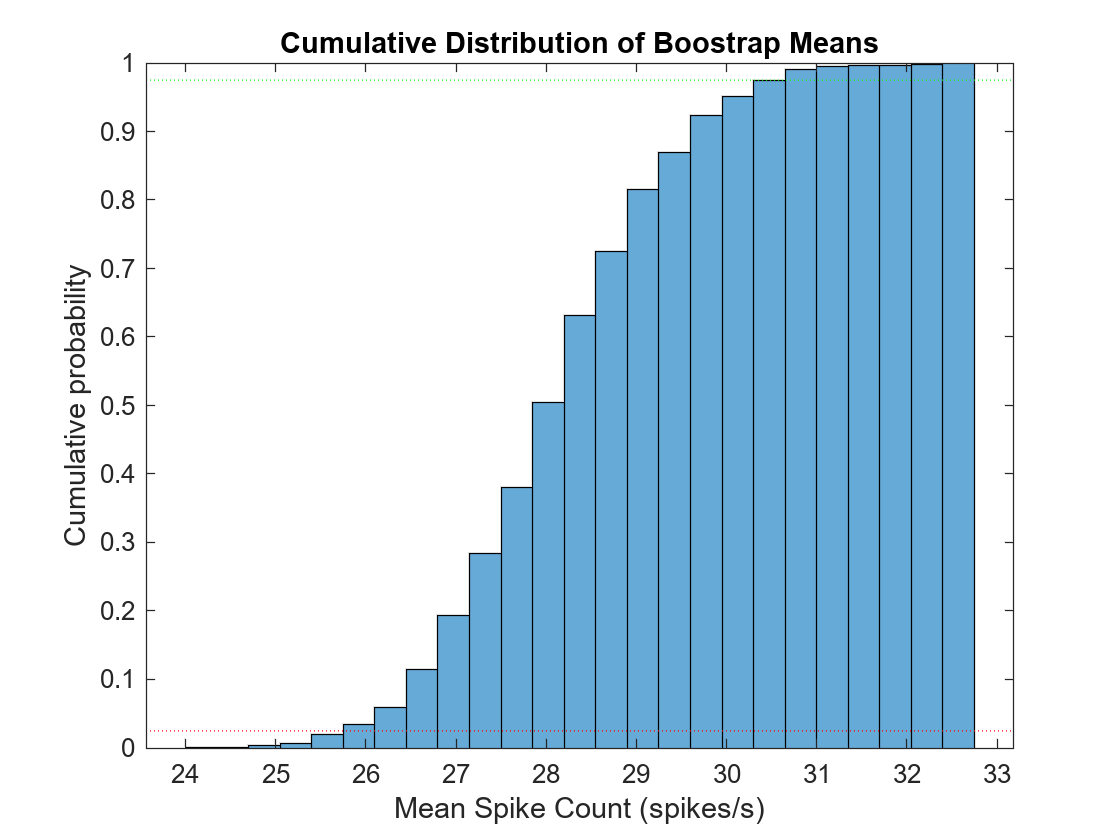

histogram(meanRate,25,'Normalization','cdf')
xlabel 'Mean Spike Count (spikes/s)'
ylabel 'Cumulative probability'
title 'Cumulative Distribution of Boostrap Means'
ylim([0 1])
hold on
line(xlim,[0.025 0.025],'Color','r','LineStyle',':')
line(xlim,[0.975 0.975],'Color','g','LineStyle',':')

This makes explcit that almost all values in the bootstrap distribution are below 31, and most are above 26. The dashed red and green lines show the 2.5% and 97.5% cumulative probability limits: 95% of bootstrap sets (i.e. virtual experiments) had spike counts between these two lines. So we can calculate the confidence limits as:

lower = prctile(meanRate,2.5);
upper = prctile(meanRate,97.5);
fprintf('Sample mean %3.4g (95%% CI: [%3.4g, %3.4g])',sampleMean,lower,upper);

Sample mean 28.25 (95% CI: [25.92, 30.67])

### Limitations & Options 

As should be clear from the description above, the critical assumption in the boostrap is that the sample is a decent approximation of the true underlying distribution. For small sample sizes, this is unlikely to be the case and the resulting estimates of confidence intervals will be too small. In other words, with small sample sizes (<50, but especially <20), the bootstrapped CI will suggest an accuracy of your results that is not warranted by the data. Solutions to this problem are to acquire more samples, or if you are willing to make some assumptions about the distribution of your measurements there is a so-called parametric bootstrap where the resampling is done on the basis of a known/assumed distribution rather than the empirical distribution. 

Another factor in the accuracy of the confidence limits is the number of bootstrap sets. If you are only interested in the inter quartile range (25%-75%), then 200 bootstrap sets can be sufficient, but if you want to say something about values that are, by definition, more rare, a larger number of bootstrap sets is needed. For 95% confidence limts,1000 sets should be enough,but if your compute power allows it, there is no harm in using 10k. In general, the smallest one-tailed confidence limit you can compute based on bootstrapping is `1./nrBootstrapSets`.

The `bootstrp` function is convenient and has built-in parallelization options that can speed up your computations and it has various options to pass not just a vector of samples,  but also other input parameters to your analysis function.  With this functionality, and the fact that the `bootfun` (i.e. the analysis function passed to `boostrp` ) can be anything you like, the possibilities for bootstrapping are endless.

Some use the standard deviation of the bootstrap distribution to estimate confidence intervals. For many statistics (i.e. values that are bootstrapped - on the horizontal axis of the bootstrap histogram), the bootstrap distribution tends towards a normal distribution (for a large number of bootstrap sets). In those cases, the standard deviation is an appropriate measure and we can calculate the confidence interval parametrically with the inverse of the cumulative normal distribution (Please note that we are using the standard *deviation* of the bootstrap distribution here, not the standard *error*!)

upper = norminv(0.975,mean(meanRate),std(meanRate));
lower = norminv(0.025,mean(meanRate),std(meanRate));
fprintf('Sample mean %3.4g (95%% CI: [%3.4g, %3.4g])',sampleMean,lower,upper);

Sample mean 28.25 (95% CI: [25.88, 30.6])

As you can see, these estimates are pretty close to the direct estimates above .Although I would advise against this approach in general (why make the assumption of normality if you don't have to?), this approach can be useful in cases where computing a large number of bootstrap sets is computationally prohibitive. With 100 sets you can estimate the mean and standard deviation quite well and if the distribution is normal, you can use that to estimate the 95% confidence limits (even when the direct calculation of those limits would be quite inaccurate for just 100 sets). 

## Null Hypothesis Testing with Permutation tests

Given that the boostrap procedure can generate a confidence interval for any value that you estimate from data, it also gives you a statistical significance test. For instance, if our hypothesis was that neuron A fired at 35 spk/s, then we can reject that hypothesis because the 95% confidence interval of the mean spike count does not overlap with 35 spk/s (i.e. we are 95% certain that the mean spike count is not 35 spk/s). This is analogous to the p<0.05 criterion.  While this is not wrong, there are more explicit ways to perform hypothesis testing using an approach that also uses resampling.

We are testing whether the firing rate of a neuron is affected by the injection of a drug. Let's generate some ground truth data:

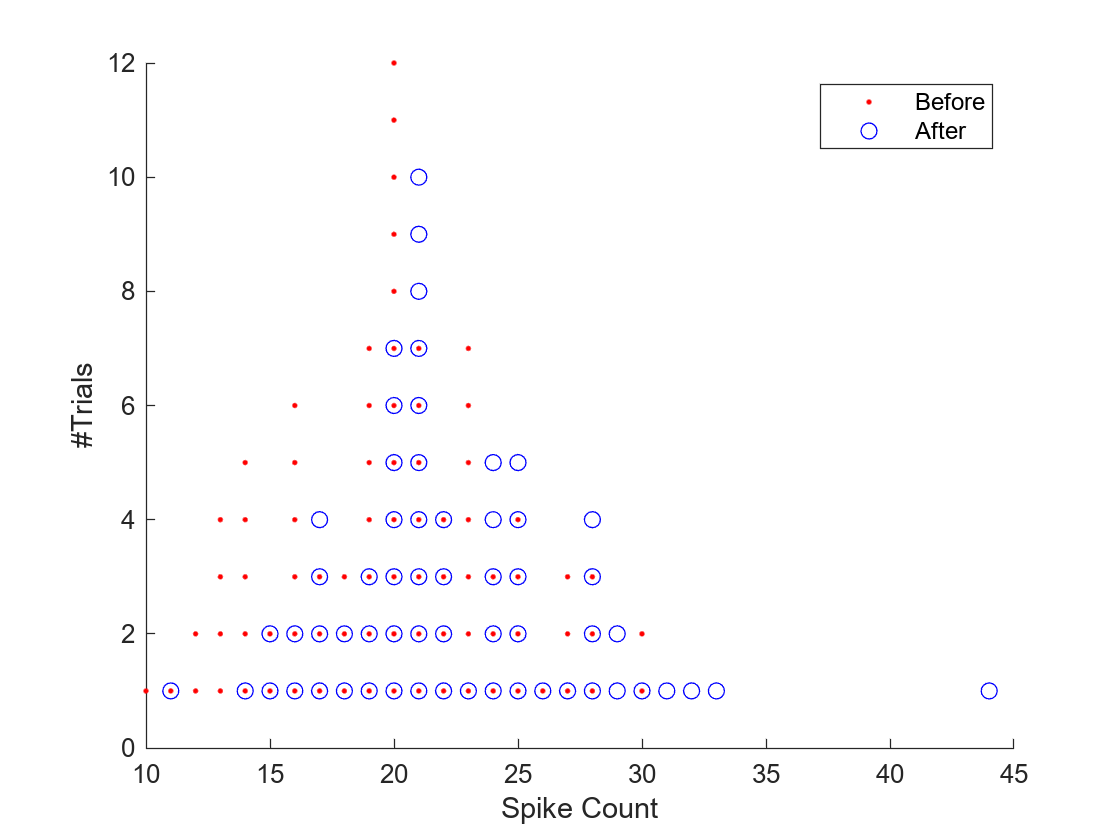

rng default;
clf;
nrTrialsAfter = 60;
nrTrialsBefore= 80;
rateBefore = 20;
rateAfter  = 21;
spikeCountBefore= poissrnd(rateBefore ,nrTrialsBefore,1);
spikeCountAfter= poissrnd(rateAfter ,nrTrialsAfter,1);
% Determine histograms (and show them)
[countTrialsBefore,nrSpikesBefore,hB] = countSpikes(spikeCountBefore,'r.');
[countTrialsAfter,nrSpikesAfter,hA] = countSpikes(spikeCountAfter,'bo');
legend([hB hA],'Before','After')

The histograms shows that there is a tendency to lower rates (in the 15-20 spk/s range) before the drug injection, and higher rates ~30 spk/s after the drug injection. But is this difference statistically significant?  This requires testing the null hypothesis that the difference between the firing rate before and after drug injection is zero. We can* simulate that null hypothesis *easily by merging the trials from the before and after coditions:

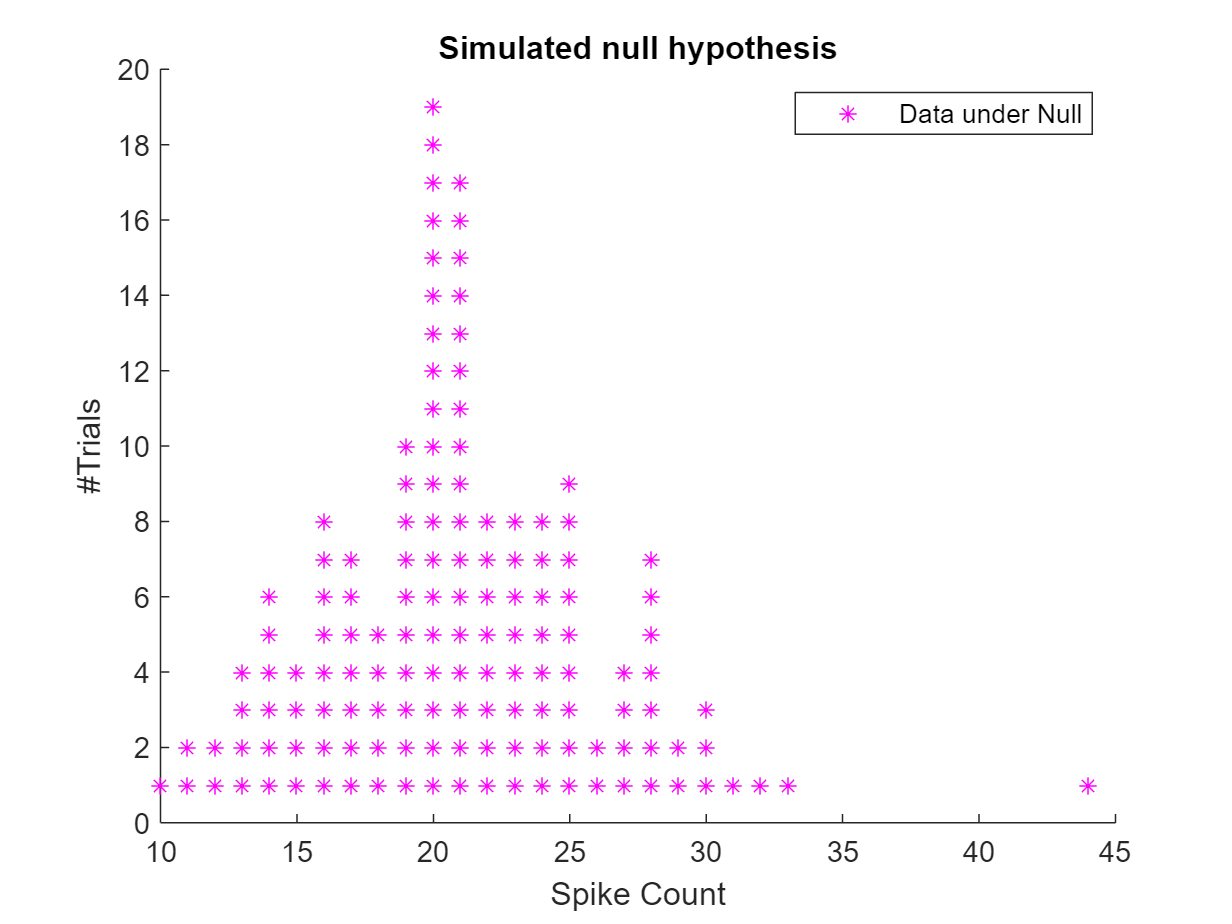

% Under the null hypothesis all trials are equal, so join them in one
% vector
spikeCountNull = [spikeCountBefore; spikeCountAfter];
% Then compute and visualize the histogram
clf
[countTrialsNull,nrSpikesNull,hB] = countSpikes(spikeCountNull,'Color',[1 0 1],'Marker','*','LineStyle','None');
title 'Simulated null hypothesis'
legend(hB,'Data under Null')

Under the null hypothesis, there are no blue dots and no red dots, they are all the same, let's say purple dots. So, if the null hypothesis is true, then the purple dot distribution shows the possible trials of our experiment. Based on this distribution we can perform virtual experiments that simulate the outcomes under the null hypothesis.

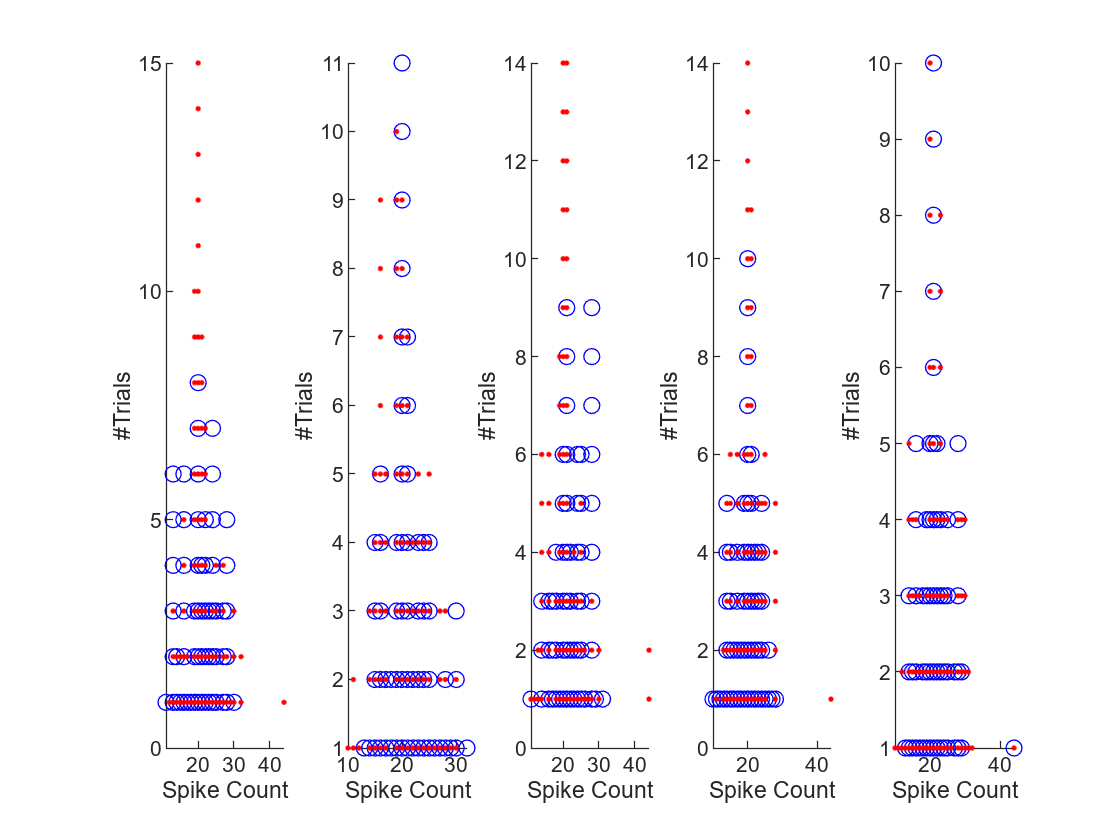

nrBoostrapSets = 1000;
nrSetsToShow = 5;
totalNrTrials = numel(spikeCountNull);
meanDifferenceNull = nan(nrBootstrapSets,1);
figure;
clf;
for i=1:nrBootstrapSets
    aTrialsNull = randi(totalNrTrials,[nrTrialsAfter 1]); % nrTrials for condition After
    bTrialsNull = randi(totalNrTrials,[nrTrialsBefore 1]); % nrTrials for condition Before
    
    shuffleA  = spikeCountNull(aTrialsNull);
    shuffleB  = spikeCountNull(bTrialsNull);
    if i<=nrSetsToShow
        subplot(1,nrSetsToShow,i);
        countSpikes(shuffleA,'bo');
        countSpikes(shuffleB,'r.');       
    end    
    meanAfterNull = mean(shuffleA);
    meanBeforeNull = mean(shuffleB);
    meanDifferenceNull(i) =meanAfterNull - meanBeforeNull;    
end

This shows a few of the shuffled bootstrap sets. Red and blue data points largely overlap, as they should, because they are drawn from the same (null) distribution. For each of the shuffled data sets,  we calculated the observed difference betwen the mean of the red and blue distribution. We can visualize this as a histogram:

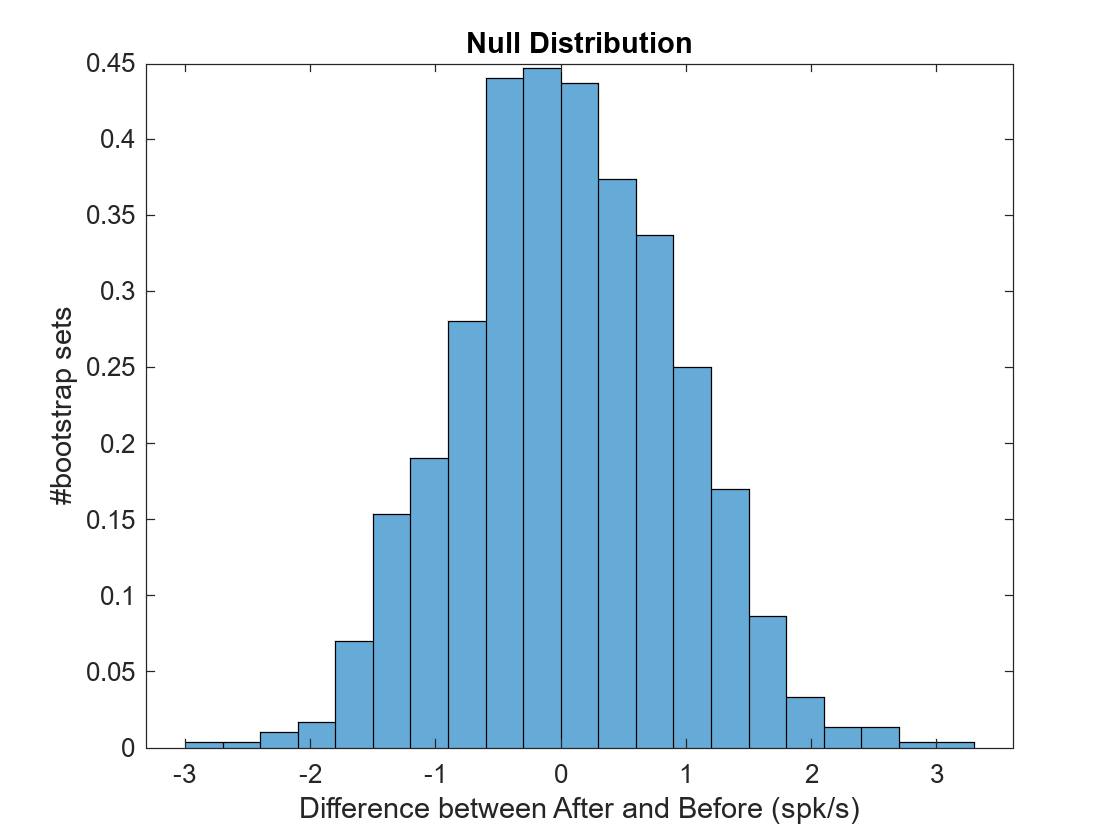

figure;
histogram(meanDifferenceNull,'Normalization','pdf')
xlabel 'Difference between After and Before (spk/s)'
ylabel '#bootstrap sets'
title 'Null Distribution'

The histogram shows that *under the null hypothesis* differences of zero are most likely and differences larger than 3 spk/s are quite unlikely. As before, we can use the CDF to quantify these probabilities:

figure;
histogram(meanDifferenceNull,'Normalization','cdf')
xlabel 'Difference between After and Before'
ylabel '#bootstrap sets'
ylim([0 1])
hold on
line(xlim,[0.025 0.025],'Color','r','LineStyle',':','LineWidth',2)
line(xlim,[0.975 0.975],'Color','g','LineStyle',':','LineWidth',2)
nrBins = 100;
[cdf,edges] = histcounts(meanDifferenceNull,nrBins,'Normalization','cdf');


From the CDF we can find the entries that are just above the 97.5% and just below the 2.5% cumulative probability (Note that the resolution (ie. the steps between successive entries in cdf) depends on the nrBins variable. If the resolution is too low, you may overestimate the confidence intervals).

ixUpper = find(cdf>0.975,1,'first'); % First above the 97.5%
upper = edges(ixUpper);
ixLower = find(cdf<0.025,1,'last'); % last below the 2.5%
lower =edges(ixLower);


Finally, we determine the actual observed difference between the spike count before and after drug injection:

actualDifference = mean(spikeCountAfter)-mean(spikeCountBefore)

actualDifference = 2.5750

and compare this to the cumulative distribution: 

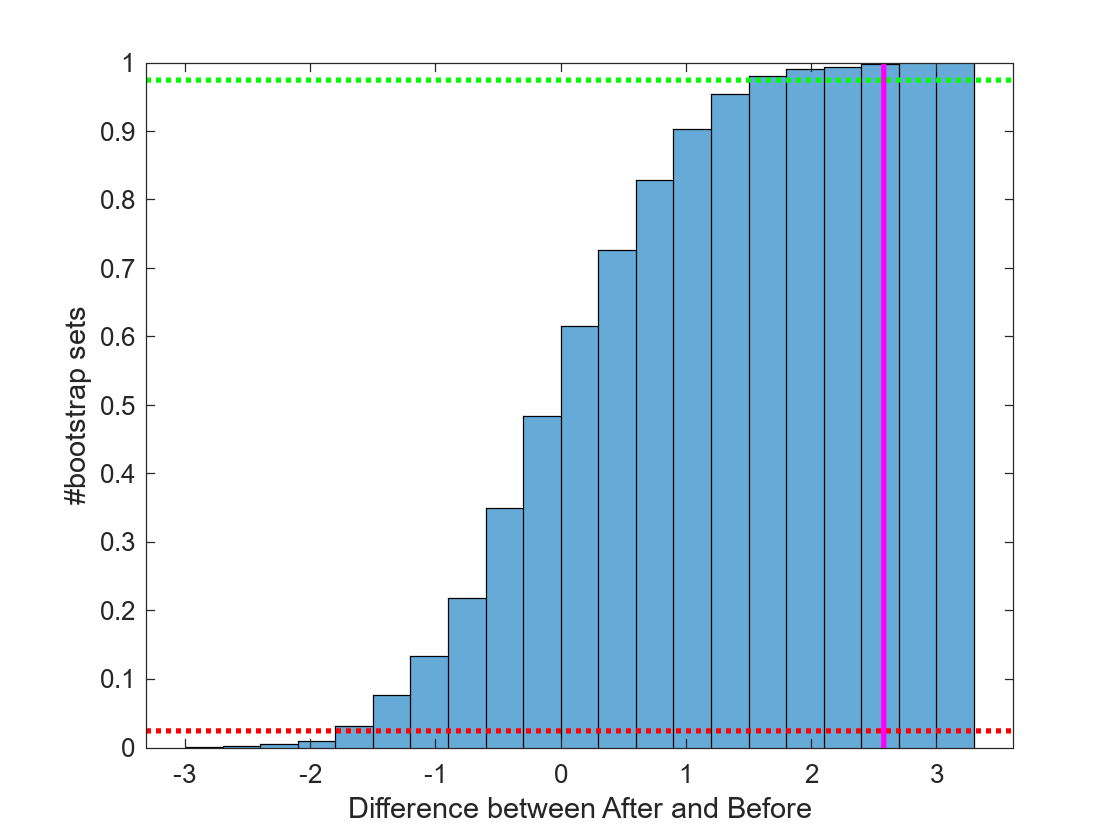

hold on
plot([actualDifference actualDifference],ylim,'m','LineWidth',2)

The graph shows that the `actualDifference` lies in the upper tail end of the cumulative distribution. That implies that the `actualDifference` is not a common observation if the null hypothesis is true.We can make this more precise by rephrasing what the `lower` and `upper` values mean: if the null hypothesis is correct, then we can state with 95% probabilitiy that differences are between the `lower` and `upper` value. But this implies that if we observe a value outside this range, then the probability that the null hypothesis is true is less than 5%. That is exactly the null hypothesis test we were looking for. This test is equivalent to a two-sided T-test, except that the permutation test makes no assumptions about the underlyng distribution. Hence, you can apply it to Poisson distributed spike counts, or any other measurement or derived quantity you like. 

rejectNull = actualDifference> upper | actualDifference < lower

rejectNull = logical
   1


While this comparison only gives an answer whether the null hypothesis can be rejected at a given significance level (here 0.05), you can also use the null distribution to estimate the corresponding p-value. We can easily determine how many of the bootstrap sets give a value that is larger than the `actualDifference`

pAbove = sum(meanDifferenceNull>=actualDifference)/numel(meanDifferenceNull)

pAbove = 0.0030

Because Matlab uses 0/1 to represent false/true, we can also write this more compact as: 

pAbove = mean(meanDifferenceNull>=actualDifference)

pAbove = 0.0030

In either case, `pAbove` gives the probability (under the null hypothesis) of observing a value as large as `actualDifference` or larger. This is the p-value associated with a one-sided test (we only looked at "larger"). For a two-tailed test (larger or smaller), you determine the probability  of a value as extreme as the actualDifference.

For instance:

pAboveOrBelow = mean(meanDifferenceNull>=actualDifference  | meanDifferenceNull <= -actualDifference)

pAboveOrBelow = 0.0040

Which an also be written more compactly as 

pAboveOrBelow = mean(abs(meanDifferenceNull)>=abs(actualDifference ))

pAboveOrBelow = 0.0040

Some texts recommend to simply double the one-sided p-Value (i.e. pAbove) to get a two-sided p-value. This is only correct if the null distribution is symmetric, and in our example, this rule would lead to an over estimate of the p-value. In general, I see no good reason to make this assumption of symmetry. In fact, the reason that you are using a permutation test is probably  that you don't want to make any parametric assumptions, so don't introduce such assumptions in the final stage; simply compute the probability on both tails.

function [nrTrials,spikeCount,h] = countSpikes(count,varargin)
% Helper function to compute and visualize a spike count histogram
% INPUT
% count = list of spike count observations
% varargin: options passed verbatim to plot to show the histogram (e.g.
% 'r.'). If empty no plot is shown.
% OUTPUT
% nrTrials = number of trials with a specific spike count
% spikeCount = corresponding number of spikes.
%
% BK - Dec 2020

if nargin <2
    plotIt = false;
else
    plotIt =true;
end
% Count unique spike count values using histcounts
edges = 0:max(count)+1;
spikeCount = edges(1:end-1);
nrTrials = histcounts(count,edges);

% Visualize the histograms if requested.
if plotIt
    hold on
    for i=1:numel(spikeCount)
             h = plot(repmat(spikeCount(i),[nrTrials(i) 1]),1:nrTrials(i),varargin{:});
    end
    xlabel 'Spike Count'
    ylabel '#Trials'    
end

end